# Image and Video Processing - Task 2

## Otsu Thresholding

Daniel Kuknyo - [Y80L35]

### Read and setup

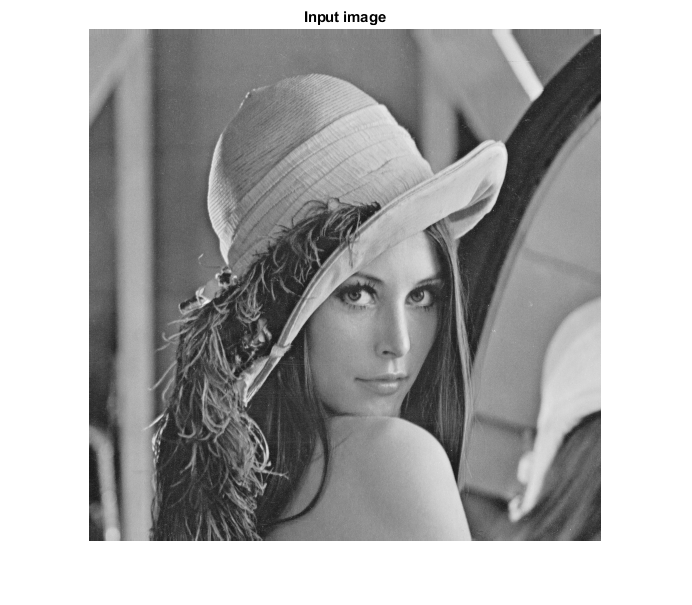

clear all; clc;

% Parameters
imname = 'Lenna.png';

img = uint8(im2gray(imread(imname)));
figure;
imshow(img);
title('Input image');

### Creating histogram

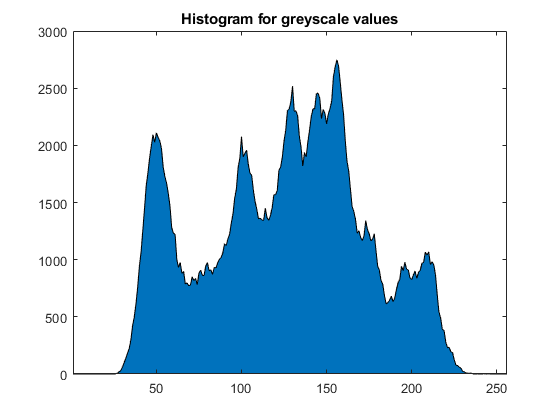

otsu_hist = zeros(1, 256);

for i = 1:size(img, 1)
    for j = 1:size(img, 2)
        grey_val = img(i, j) + 1;
        otsu_hist(1, grey_val) = otsu_hist(1, grey_val) + 1;
    end
end

figure;
area(otsu_hist);
xlim([1,256]);
title('Histogram for greyscale values')

% Summing for all pixels
s = sum(otsu_hist, 2);

% Compute greyscale value weights
p_i = zeros(1,256);
for i = 1:256
    p_i(1, i) = otsu_hist(1, i) / s;
end

% Compute mean
mu = 0;
for i = 1:256
    mu = mu + i * p_i(1, i); 
end
disp(mu)

  125.0425



% Compute squared deviance
sigma = 0;
for i = 1:256
    sigma = sigma + (i - mu)^2 * p_i(1, i);
end
disp(sigma);

   2.2902e+03



### Calculating the optimal threshold value

% Calculate q1 and q2
q1 = zeros(1,256);
q2 = zeros(1,256);

q1(1, 1) = p_i(1, 1);
q2(1, 1) = 1 - q1(1, 1);

for t = 2:256
    q1(1, t) = q1(1, t-1) + p_i(1, t);
    q2(1, t) = 1 - q1(1, t);
end

% Calculate mu1 from q1
mu1 = zeros(1, 256);
mu1(1, 1) = 0;
for t = 2:256
    numer = q1(1, t-1) * mu1(1, t-1) + t * p_i(1, t);
    denom = q1(1, t);
    
    if(numer == 0 && denom == 0)
        continue;
    else
        mu1(1, t) = numer / denom;
    end
end

% Calculate mu2 from mu1 and q1
mu2 = zeros(1, 256);
mu2(1, 1) = 0;
for t = 2:256
    numer = mu - q1(1, t) * mu1(1, t);
    denom = 1 - q1(1, t);

    if(numer == 0 && denom == 0)
        continue;
    else
        mu2(1, t) = numer / denom;
    end
end

% Calculate between class deviation
max_t = -1;
max_sigma = -1; 
for t = 1:256
    sigma_b = q1(1, t) * q2(1, t) * ((mu1(1, t) - mu2(1, t))^2);
    
    if(sigma_b > max_sigma)
        max_sigma = sigma_b;
        max_t = t;
    end
end

### Creating the thresholded image

output_image = img;

for i = 1:size(output_image, 1)
    for j = 1:size(output_image, 2)
        if(output_image(i,j)<=max_t)
            output_image(i,j) = 0;
        else
            output_image(i,j) = 255;
        end
    end
end

disp(max_t);

   118



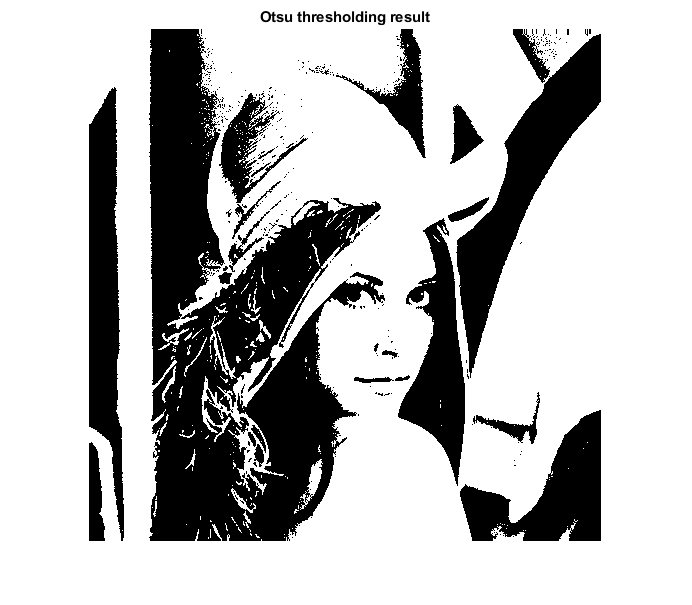


fig = figure;
imshow(output_image)
title('Otsu thresholding result');
saveas(fig, strcat('Otsu_', imname));